Define the transfer functions

% Define Laplace variable
s = tf('s');

% Define the transfer function matrix G(s) with delays
G11 = 119 * exp(-5 * s) / (21.7 * s + 1);
G12 = 153 * exp(-5 * s) / (337 * s + 1);
G13 = -2.1 * exp(-5 * s) / (10 * s + 1);

G21 = 37 * exp(-5 * s) / (500 * s + 1);
G22 = 76.7 * exp(-5 * s) / (28 * s + 1);
G23 = -5 * exp(-5 * s) / (10 * s + 1);

G31 = 93 * exp(-5 * s) / (500 * s + 1);
G32 = -66.7 * exp(-5 * s) / (166 * s + 1);
G33 = -103.3 * exp(-5 * s) / (23 * s + 1);

Combine into a transfer function matrix

G = [G11 G12 G13;
     G21 G22 G23;
     G31 G32 G33];
G

G =
 
  From input 1 to output...
                      119
   1:  exp(-5*s) * ----------
                   21.7 s + 1
 
                      37
   2:  exp(-5*s) * ---------
                   500 s + 1
 
                      93
   3:  exp(-5*s) * ---------
                   500 s + 1
 
  From input 2 to output...
                      153
   1:  exp(-5*s) * ---------
                   337 s + 1
 
                     76.7
   2:  exp(-5*s) * --------
                   28 s + 1
 
                     -66.7
   3:  exp(-5*s) * ---------
                   166 s + 1
 
  From input 3 to output...
                     -2.1
   1:  exp(-5*s) * --------
                   10 s + 1
 
                      -5
   2:  exp(-5*s) * --------
                   10 s + 1
 
                    -103.3
   3:  exp(-5*s) * --------
                   23 s + 1
 
Continuous-time transfer function.


Calculate the steady-state gain matrix by substituting s=0

K = dcgain(G);
disp('Gain matrix at steady state:');

Gain matrix at steady state:


K

K =   119.0000  153.0000   -2.1000
   37.0000   76.7000   -5.0000
   93.0000  -66.7000 -103.3000


Calculate the inverse of the steady-state gain matrix

K_inv = inv(K);

Calculate the RGA matrix

rga_matrix = K .* (K_inv.');
disp('RGA matrix:');

RGA matrix:


rga_matrix

rga_matrix =     2.1896   -1.1446   -0.0449
   -1.3147    2.0677    0.2470
    0.1252    0.0769    0.7979


## Dynamic RGA

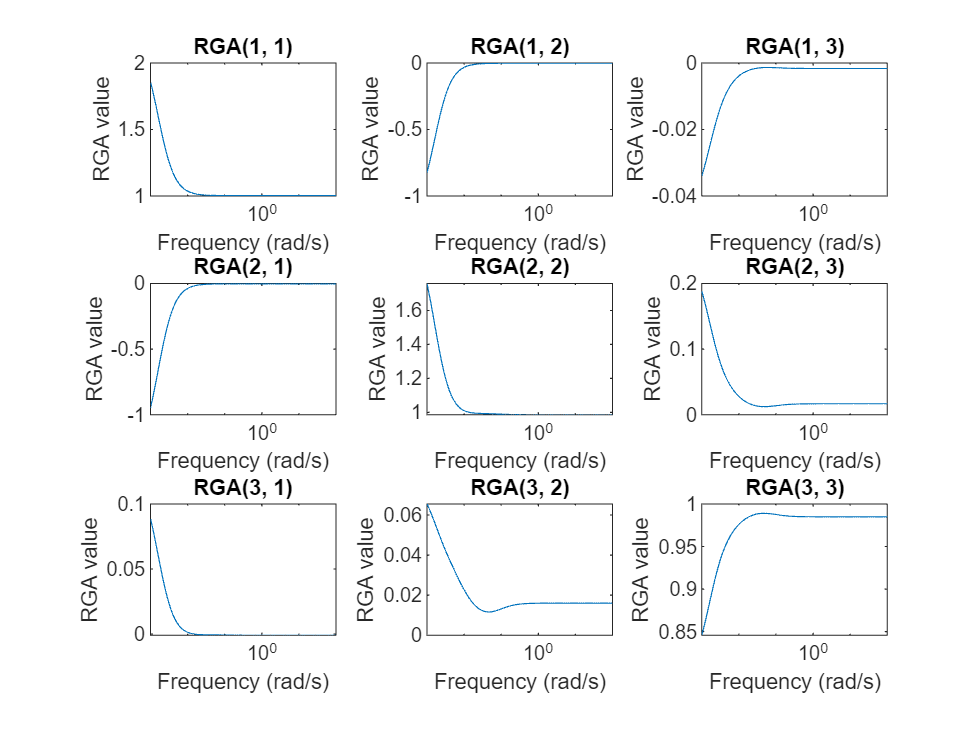

% Define the frequency range
w = logspace(-3, 2, 100);  % From 0.001 to 100 rad/s

% Get the steady-state (s = 0) gain matrix
K = dcgain(G);   % dcgain calculates the static gain of the system

% Get the sign of the static gain matrix to account for directionality
Ksgn = sign(K);

% Preallocate kw for storing singular values
n = size(G, 1);  % Number of inputs/outputs (assuming square system)
kw = zeros(n, n, length(w));  % Preallocate the singular value matrix

% Loop through each transfer function element and compute singular values over frequency
for i = 1:n
    for j = 1:n
        kw(i, j, :) = Ksgn(i, j) * sigma(G(i, j), w);  % Calculate singular values across frequency range
    end
end

% Preallocate L for dynamic RGA
L = zeros(n, n, length(w));

% Loop through each frequency and compute the dynamic RGA
for k = 1:length(w)
    Kp = kw(:, :, k);         % Get the singular values at frequency w(k)
    rga = Kp .* inv(Kp)';     % Calculate dynamic RGA matrix for this frequency
    L(:, :, k) = rga;         % Store the dynamic RGA result
end

% ----- Plot the dynamic RGA for each element as a function of frequency -----
figure;

for i = 1:n
    for j = 1:n
        subplot(3, 3, (i-1)*3 + j);  % Create 3x3 subplots
        semilogx(w, squeeze(L(i, j, :)));
        title(sprintf('RGA(%d, %d)', i, j));
        xlabel('Frequency (rad/s)');
        ylabel('RGA value');
    end
end